# Numerical Stability and Condition Numbers

## Introduction

Numerical stability and condition numbers are crucial concepts in numerical analysis and linear algebra, particularly when solving systems of linear equations. Numerical stability refers to how errors are propogated through an algorithm, while the condition number of a matrix measures the sensitivity of the solution to perturbations in the input data.

## Numerical stability

Numerical stability of an algorithm indicates how errors, such as round-off errors or approximation errors, affect the outcome of the algorithm. An algorithm is considered numerically stable if small changes in the input or intermediate steps result in small changes in the output.

### Types of Errors:

- **Round-off Error:** Errors due to the finite precision of compute arithmetic.

- **Truncation Error:** Errors due to approximating an infinite process by a finite one.

## Condition Numbers

The condition number of a matrix $A$ provides a measure of how the solution to a system of linear equations $Ax=b$ will chnage with respect to small changes in the input data $b$ or the matrix $A$. A matrix with a high condition number is said to be ill-conditioned, which implies that even small errors in the input can lead to large errors in the output.

## Mathematical Definition

The condition number $k(A)$ of a matrix $A$ is defined as:


$$k(A) = || A || \cdot || A^{-1}||$$


where $|| \cdot ||$ denotes a matrix norm. Commonly used norms include the $\infty$-norm, 1-norm, and 2-norm.

## Example calculatiuon of Condition Number

Consider the matrix $A$:

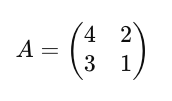

To compute the condition number using the $\infty$-norm:

- Calculate the $\infty$-norm of $A$: $||A||=\text{max}\Big(\sum^n_{j=1}|A_{ij}|\Big)=\text{max}(6,4)=6$.

- Calulate the inverse of $A$: $A^{-1} \left({}^{-0\ldotp 5}_{1\ldotp 5}^1_{-2}\right)$

- Calculate the $\infty$-norm of $A^{-1}$: $||A^{-1}||_{\infty}=\text{max}\Big(\sum^n_{j=1}|a_{ij}^{-1}|\Big)=\text{max}(1.5,3)=3$.

- Compute the condition number: $k(A) = ||A||_{\infty} \cdot ||A^{-1}||_{\infty}=6\times3=18$.

The computation in point 4 indicates that $A$ is moderately ill-conditioned.

# Numerical Stability and Condition Numbers in Financial Risk Analysis

## Practical Scenario: Portfolio Risk Analysis

In this example, we will assess the numerical stability and condition numbers of a covariance matrix derived from historical stock returns. This will help understand the sensitivity of the portfolio risk assessment to changes in the data.

% Step 1: Load historical return data for 5 stocks
returns = [
    0.01, 0.03, -0.02, 0.04, 0.05;
    0.02, 0.01, -0.01, 0.03, 0.04;
    -0.01, 0.04, 0.02, 0.01, -0.03;
    0.03, -0.02, 0.01, 0.02, 0.03;
    0.04, 0.01, 0.03, -0.02, 0.02
];

% Step 2: Calculate the covariance matrix
covMatrix = cov(returns)

covMatrix = 1.0e-03 *

    0.3700   -0.3400    0.0900   -0.1850    0.3300
   -0.3400    0.5300   -0.0550    0.0450   -0.3100
    0.0900   -0.0550    0.4300   -0.4450   -0.4400
   -0.1850    0.0450   -0.4450    0.5300    0.3350
    0.3300   -0.3100   -0.4400    0.3350    0.9700


% Step 3: Calculate the condition number using different norms
cond_2 = cond(covMatrix) % 2-norm (default)

cond_2 = 2.1601e+16

cond_inf = cond(covMatrix, 'inf') % Infinity norm

cond_inf = 5.5775e+17

cond_1 = cond(covMatrix,1) % 1-norm

cond_1 = 5.5775e+17

% Step 4: Analyze numerical stability by pertubing the data
% Add a small pertubation to the returns
perturbed_returns = returns + 0.001 * randn(size(returns))

perturbed_returns =     0.0086    0.0314   -0.0193    0.0389    0.0502
    0.0186    0.0103   -0.0092    0.0301    0.0399
   -0.0095    0.0402    0.0198    0.0107   -0.0319
    0.0298   -0.0184    0.0102    0.0226    0.0296
    0.0398    0.0092    0.0288   -0.0207    0.0182


% Calculate the perturbed covariance matrix
perturbed_covMatrix = cov(perturbed_returns)

perturbed_covMatrix =     0.0004   -0.0003    0.0001   -0.0002    0.0003
   -0.0003    0.0005   -0.0001    0.0000   -0.0003
    0.0001   -0.0001    0.0004   -0.0004   -0.0004
   -0.0002    0.0000   -0.0004    0.0005    0.0003
    0.0003   -0.0003   -0.0004    0.0003    0.0010


% Calculate the change in the covariance matrix
change_in_covMatrix = norm(perturbed_covMatrix - covMatrix, 'fro')

change_in_covMatrix = 8.5331e-05

% Step 5: Interpreration
% The condition numbers indicate how sensitive the covariance matrix is to changes in the returns data.
% A high condition number suggests that the covariance matrix is ill-conditioned and the portfolio risk assessment
% may be highly sensitive to small changes in the input data.

# Practice Problem

## Problem Statement

You are given historical return data for a different set of stocks. Use numerical stability and condition numbers to analyze the sensititvity of the portfolio risk assessment. Specifically, perform the following tasks:

- Load the historical returns for 5 different stocks.

- Calcualte the covariance matriax of the returns

- Calculate the condition number using different norms (2-norm, infinity norm, and 1-norm).

- Analyze numerical stability by perturbing the return data slightly and observing the changes in the covariance matrix.

- Interpret the results to understand the sensitivity of the portfolio risk assessment.